# Strong Connectivity and Kernel Graph Example

#### Source-Sink-Reacheable Digraph Example

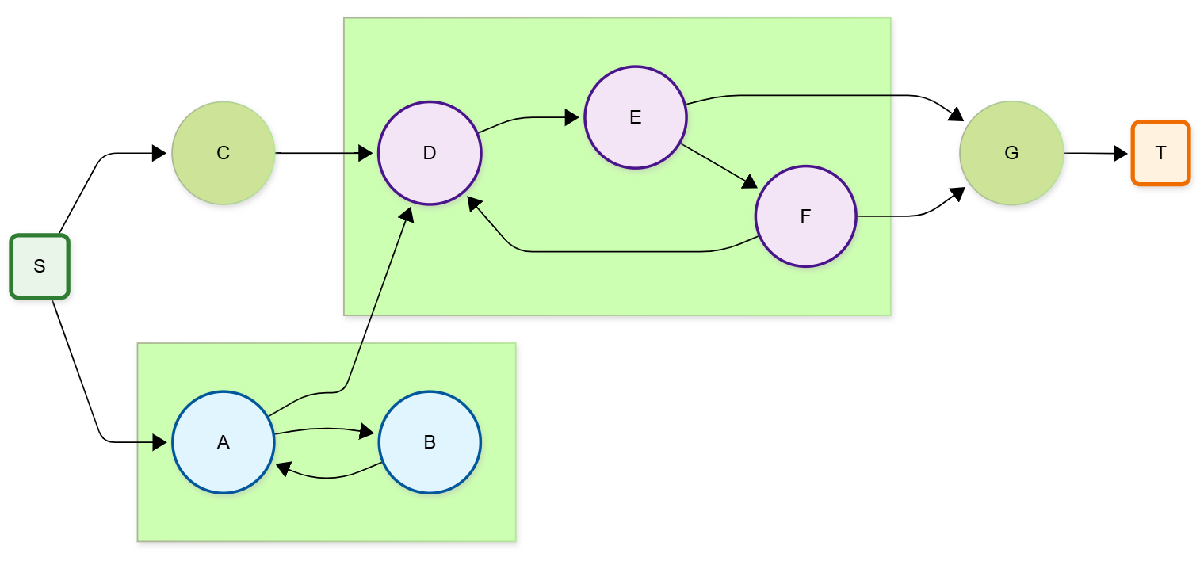

#### Weighted Adjacency Matrix

% Vertex: S(1), A(2), B(3), C(4), D(5), E(6), F(7), G(8), T(9)
A = [
  0 0.6 0 0.4 0 0 0 0 0;  % S -> A, C
  0 0 0.1 0 0.9 0 0 0 0;  % A -> B, D  
  0 1 0 0 0 0 0 0 0;      % B -> A
  0 0 0 0 1 0 0 0 0;      % C -> D
  0 0 0 0 0 1 0 0 0;      % D -> E
  0 0 0 0 0 0 0.2 0.8 0;  % E -> F, G
  0 0 0 0 0.1 0 0 0.9 0;  % F -> D, G
  0 0 0 0 0 0 0 0 1;      % G -> T
  0 0 0 0 0 0 0 0 0;      % T (sink)
]

A =          0    0.6000         0    0.4000         0         0         0         0         0
         0         0    0.1000         0    0.9000         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0    0.2000    0.8000         0
         0         0         0         0    0.1000         0         0    0.9000         0
         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0         0         0         0         0         0


nodeLabels = {'S', 'A', 'B', 'C', 'D', 'E', 'F', 'G', 'T'};

#### Check Spectral Ratio ρ(A) < 1

rho = max(real(eig(A)));
fprintf('Spectral Ratio ρ(A) = %.4f\n', rho);

Spectral Ratio ρ(A) = 0.3162


#### Compute Transitive Closure, Strong Components and Kernel Matrix

AA = logical(A);
TC=transitiveClosure(AA)

TC = 9×9 logical array
   1   1   1   1   1   1   1   1   1
   0   1   1   0   1   1   1   1   1
   0   1   1   0   1   1   1   1   1
   0   0   0   1   1   1   1   1   1
   0   0   0   0   1   1   1   1   1
   0   0   0   0   1   1   1   1   1
   0   0   0   0   1   1   1   1   1
   0   0   0   0   0   0   0   1   1
   0   0   0   0   0   0   0   0   1


SC=getStrongComponents(TC);
kM=getKernelMatrix(A,SC)

kM =          0    0.6000    0.4000         0         0         0
         0         0         0    0.9000         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.7000         0
         0         0         0         0         0    1.0000
         0         0         0         0         0         0


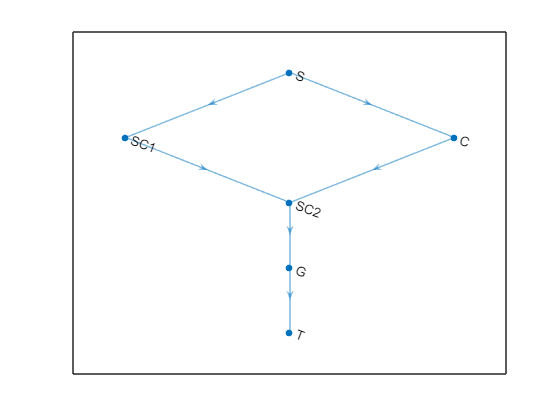

[kLabels,groupsTable]=getKernelLabels(SC,nodeLabels);
dg=digraph(kM,kLabels);
plot(dg);

disp(groupsTable')

    {'S'}    {'S'  }
    {'A'}    {'SC1'}
    {'B'}    {'SC1'}
    {'C'}    {'C'  }
    {'D'}    {'SC2'}
    {'E'}    {'SC2'}
    {'F'}    {'SC2'}
    {'G'}    {'G'  }
    {'T'}    {'T'  }



function SC=getStrongComponents(TC)
% Find the strongly connected components
% Return the membership matrix (nc,n)
    n=size(TC,1);
    grp=zeros(1,n); cnt=0;
    for u=1:n
        if ~grp(u)
            cnt=cnt+1;
            idx = TC(u,:) & TC(:,u)';  
            grp(idx)=cnt;
        end
    end
    SC=sparse(grp,1:n,true(n,1),cnt,n);
end

function kM=getKernelMatrix(A,SC)
    nc=size(SC,1);
    kM=SC*A*SC';
    kM(1:nc+1:end)=0;
end

function [kLabels,groupsTable]=getKernelLabels(SC,nodeLabels)
    [grp,~]=find(SC);
    [~,jdx,idx]=unique(grp);
    kLabels = nodeLabels(jdx);
    nrg = accumarray(idx,1);
    tmp = find(nrg>1);
    for i=1:length(tmp)
        kLabels{tmp(i)}=['SC',num2str(i)];
    end
    groupsTable=[nodeLabels;kLabels(idx)];
end